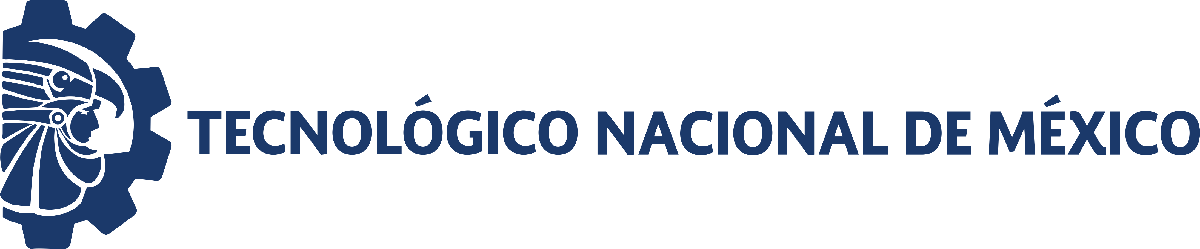                                 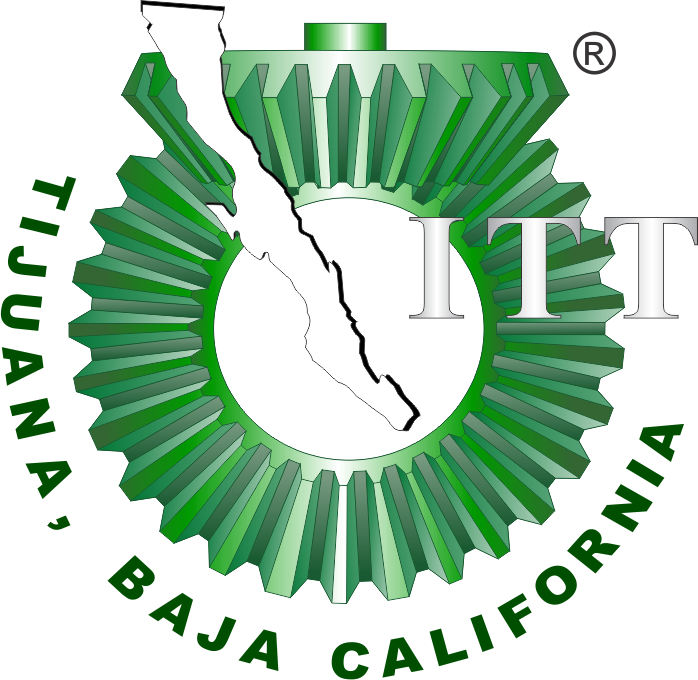

# Práctica 5: Análisis de sistemas biológicos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

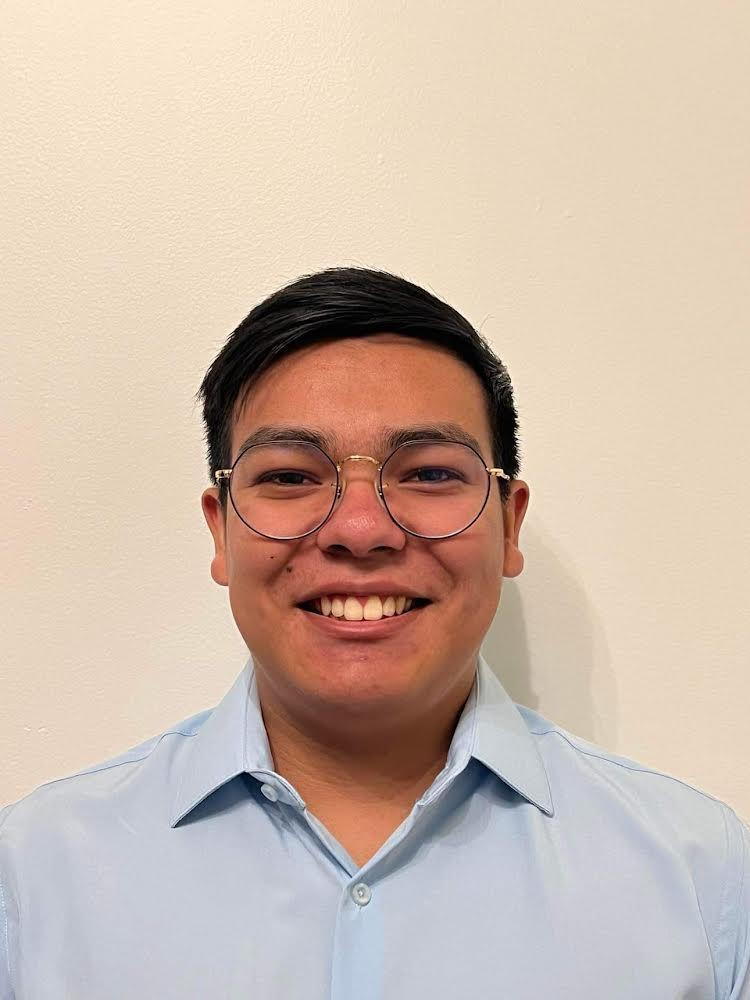

Nombre del alumno: **Alexander Torres Avila**

Número de control: **21212848**

Correo institucional: **L21212848@tectijuana.edu.mx**

Carrera: **Ing. Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

clc; clear; close all; warning('off','all')

## Parameters an initial conditions

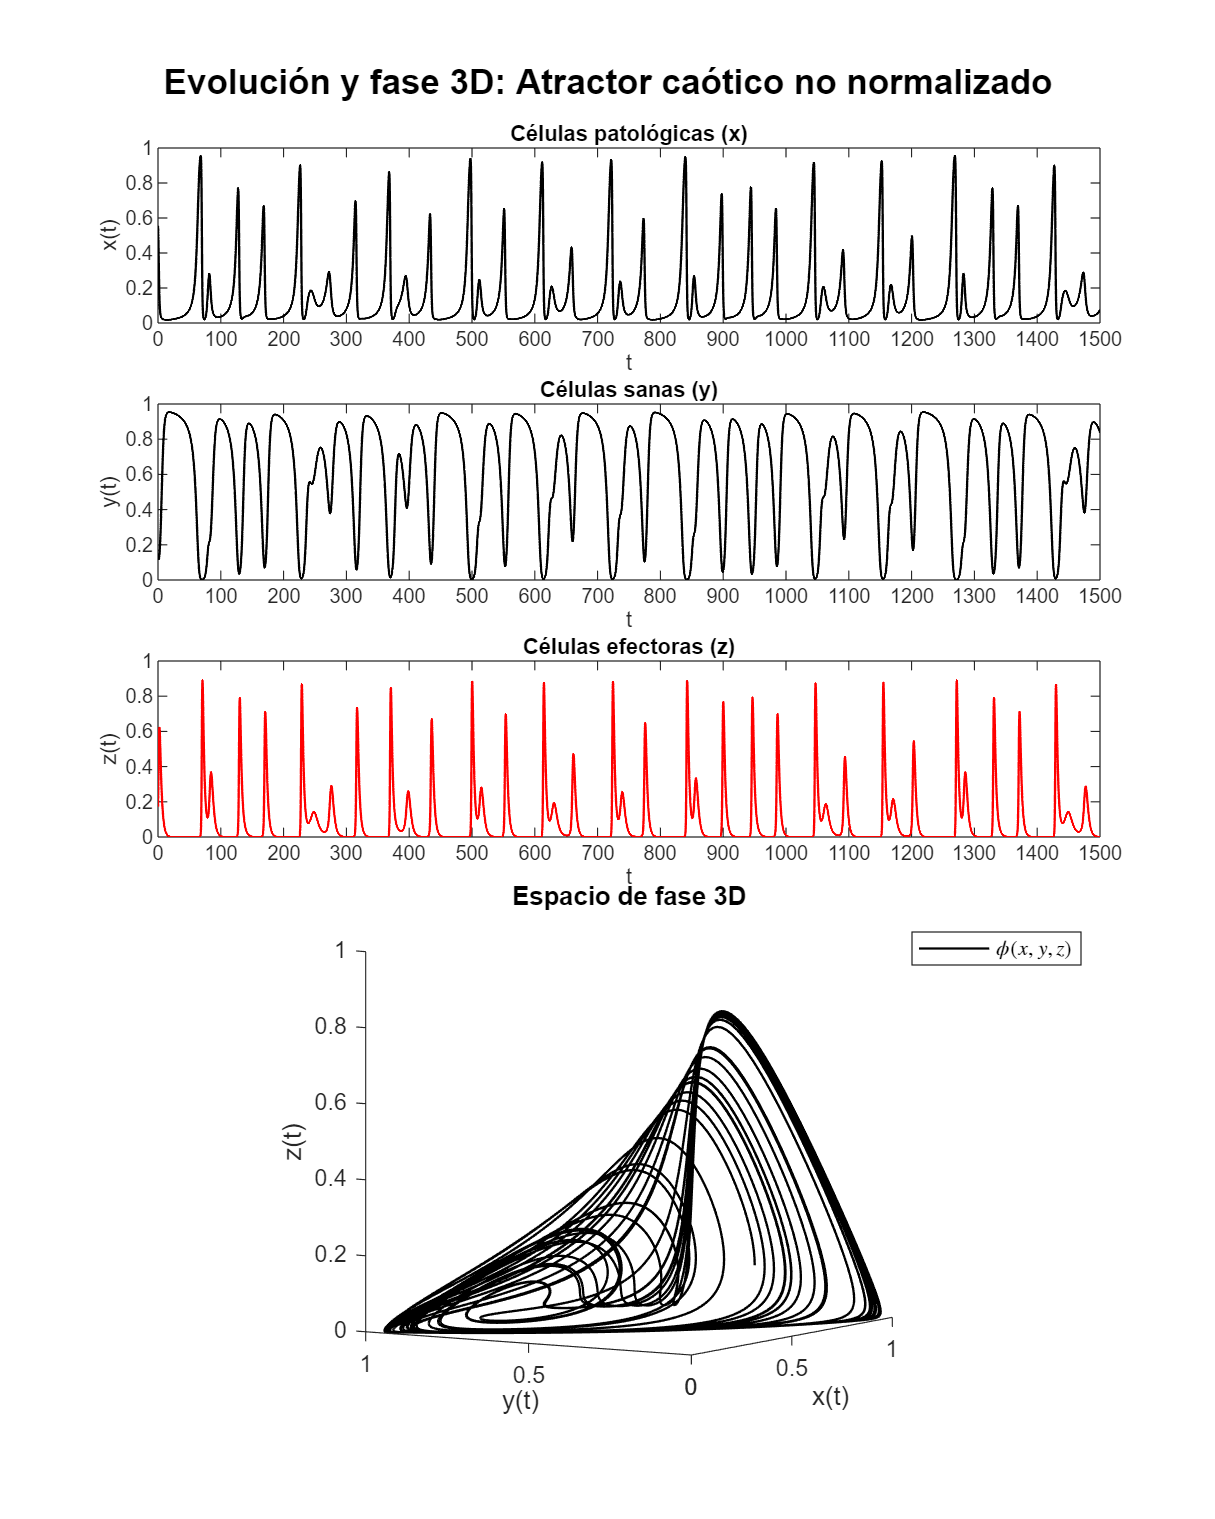

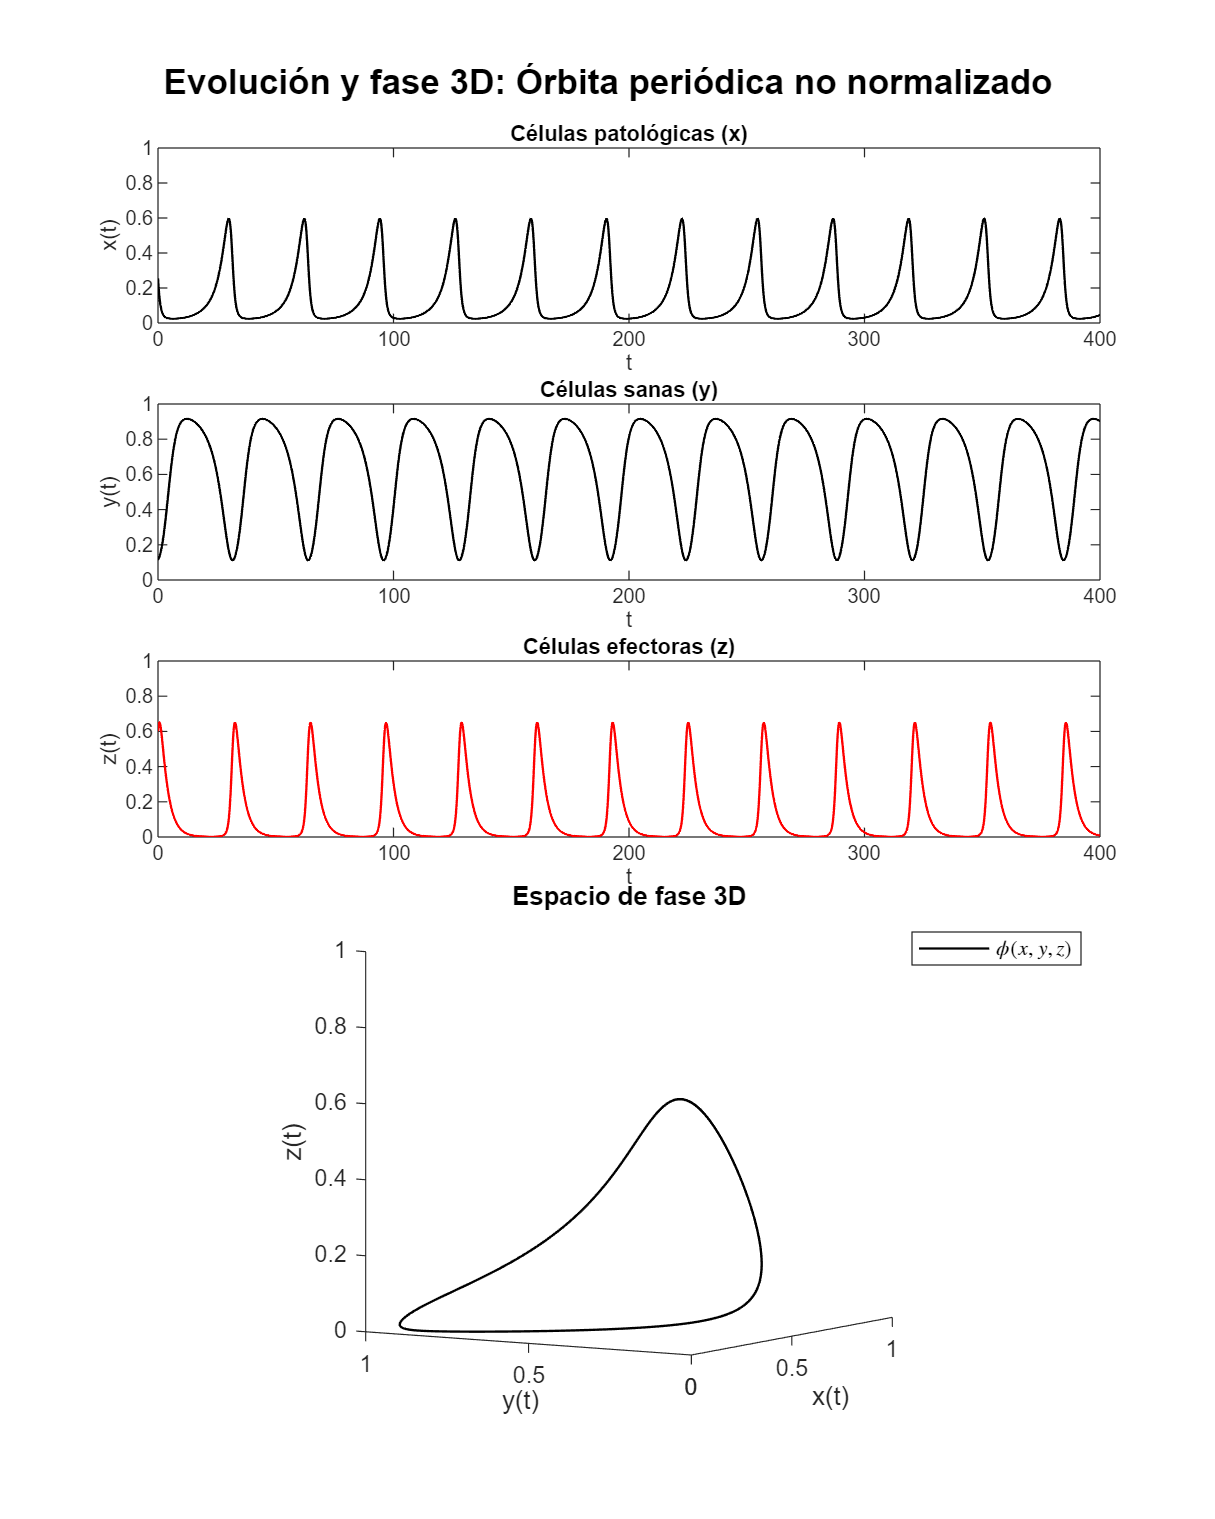

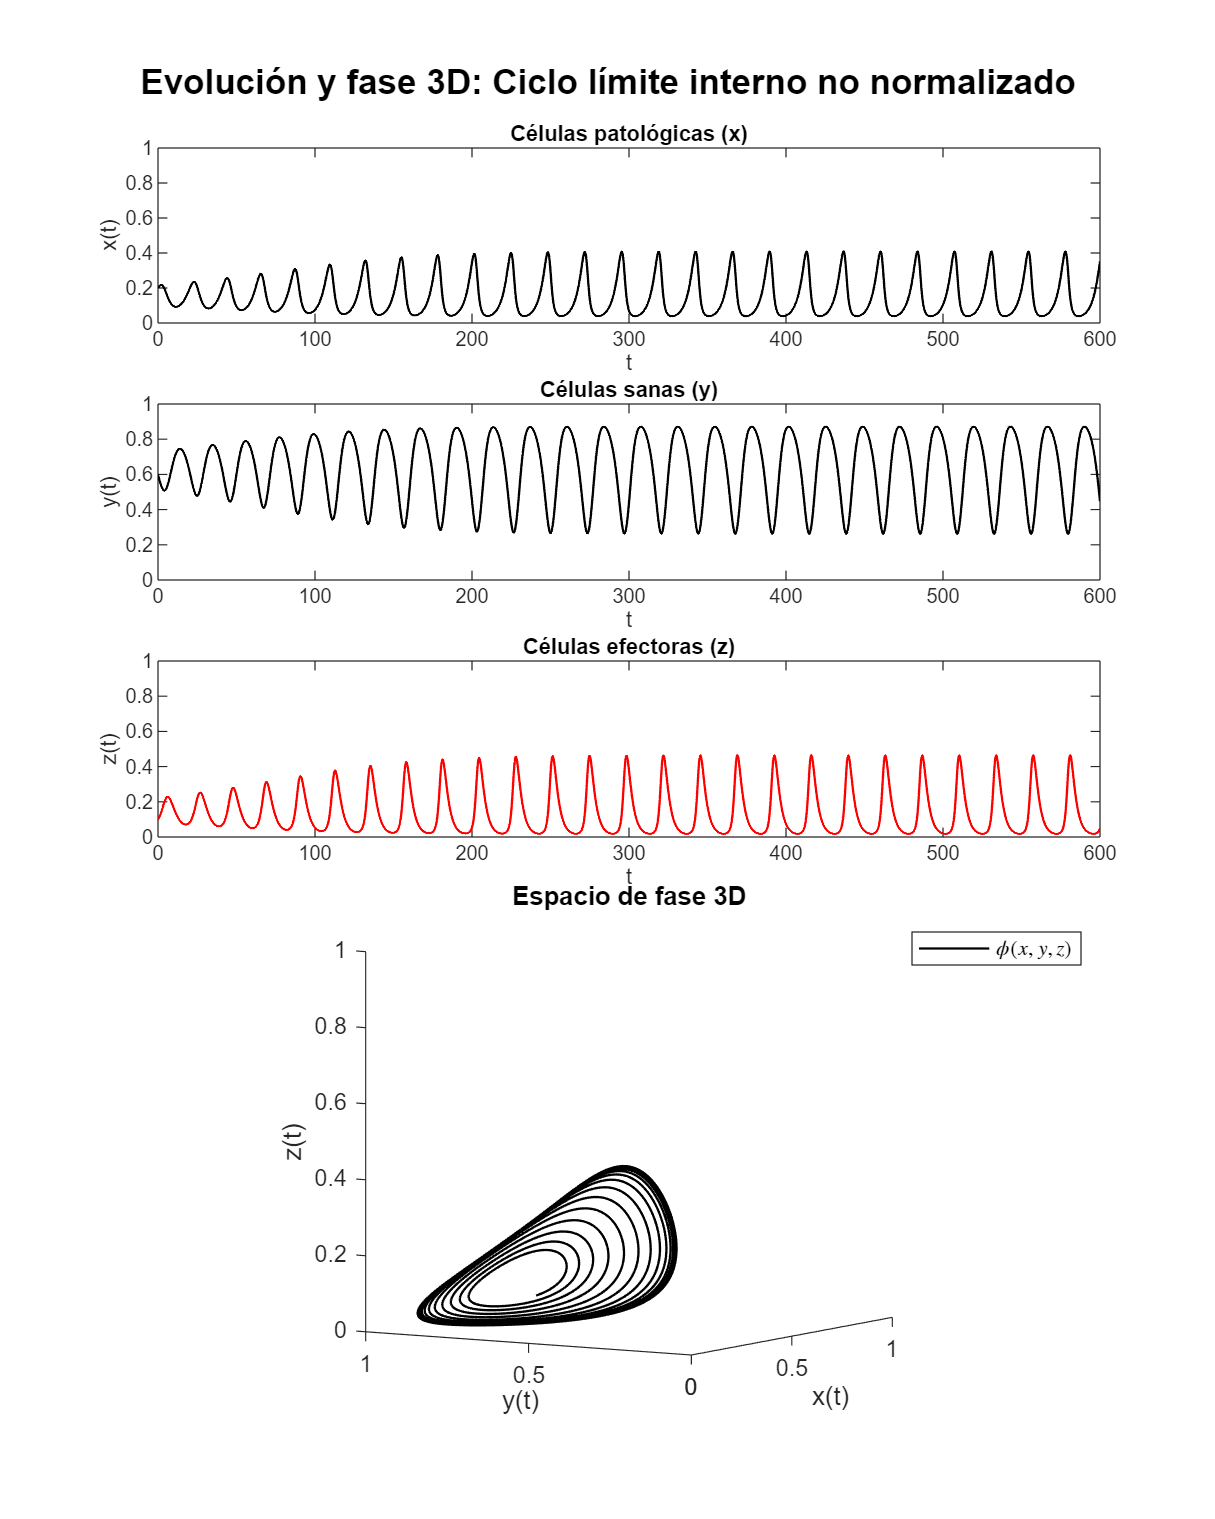

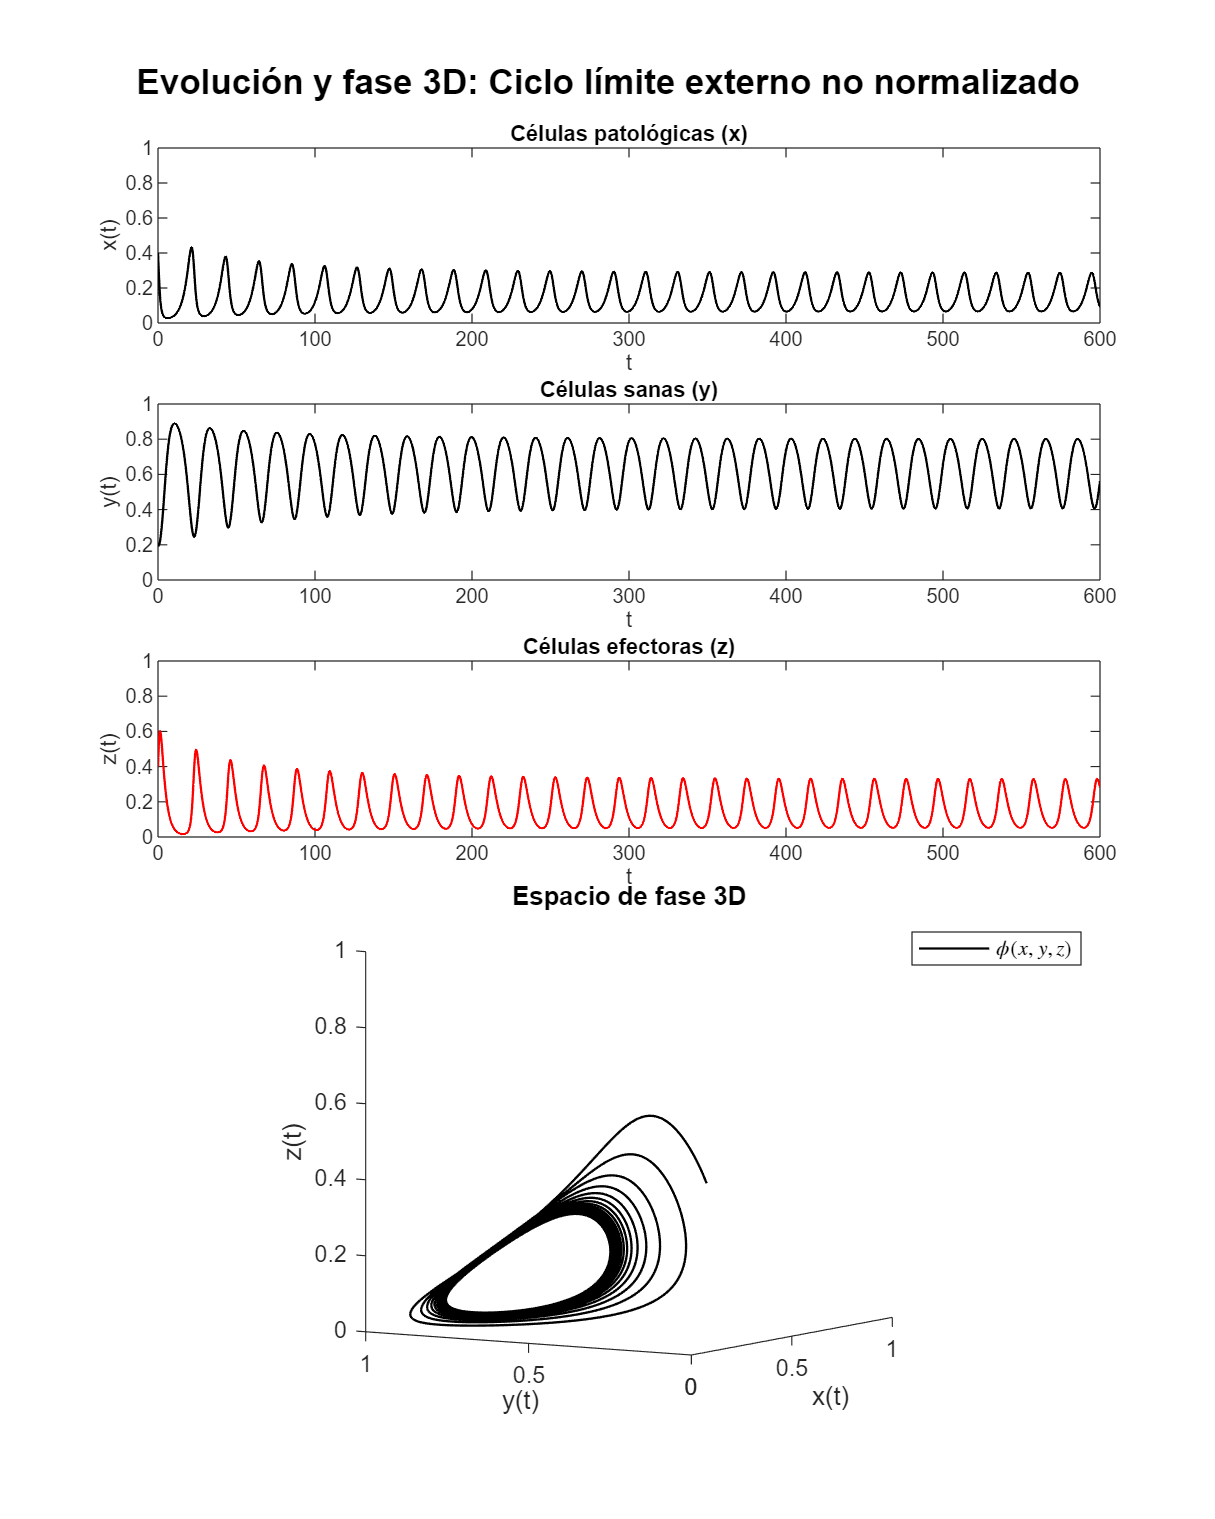

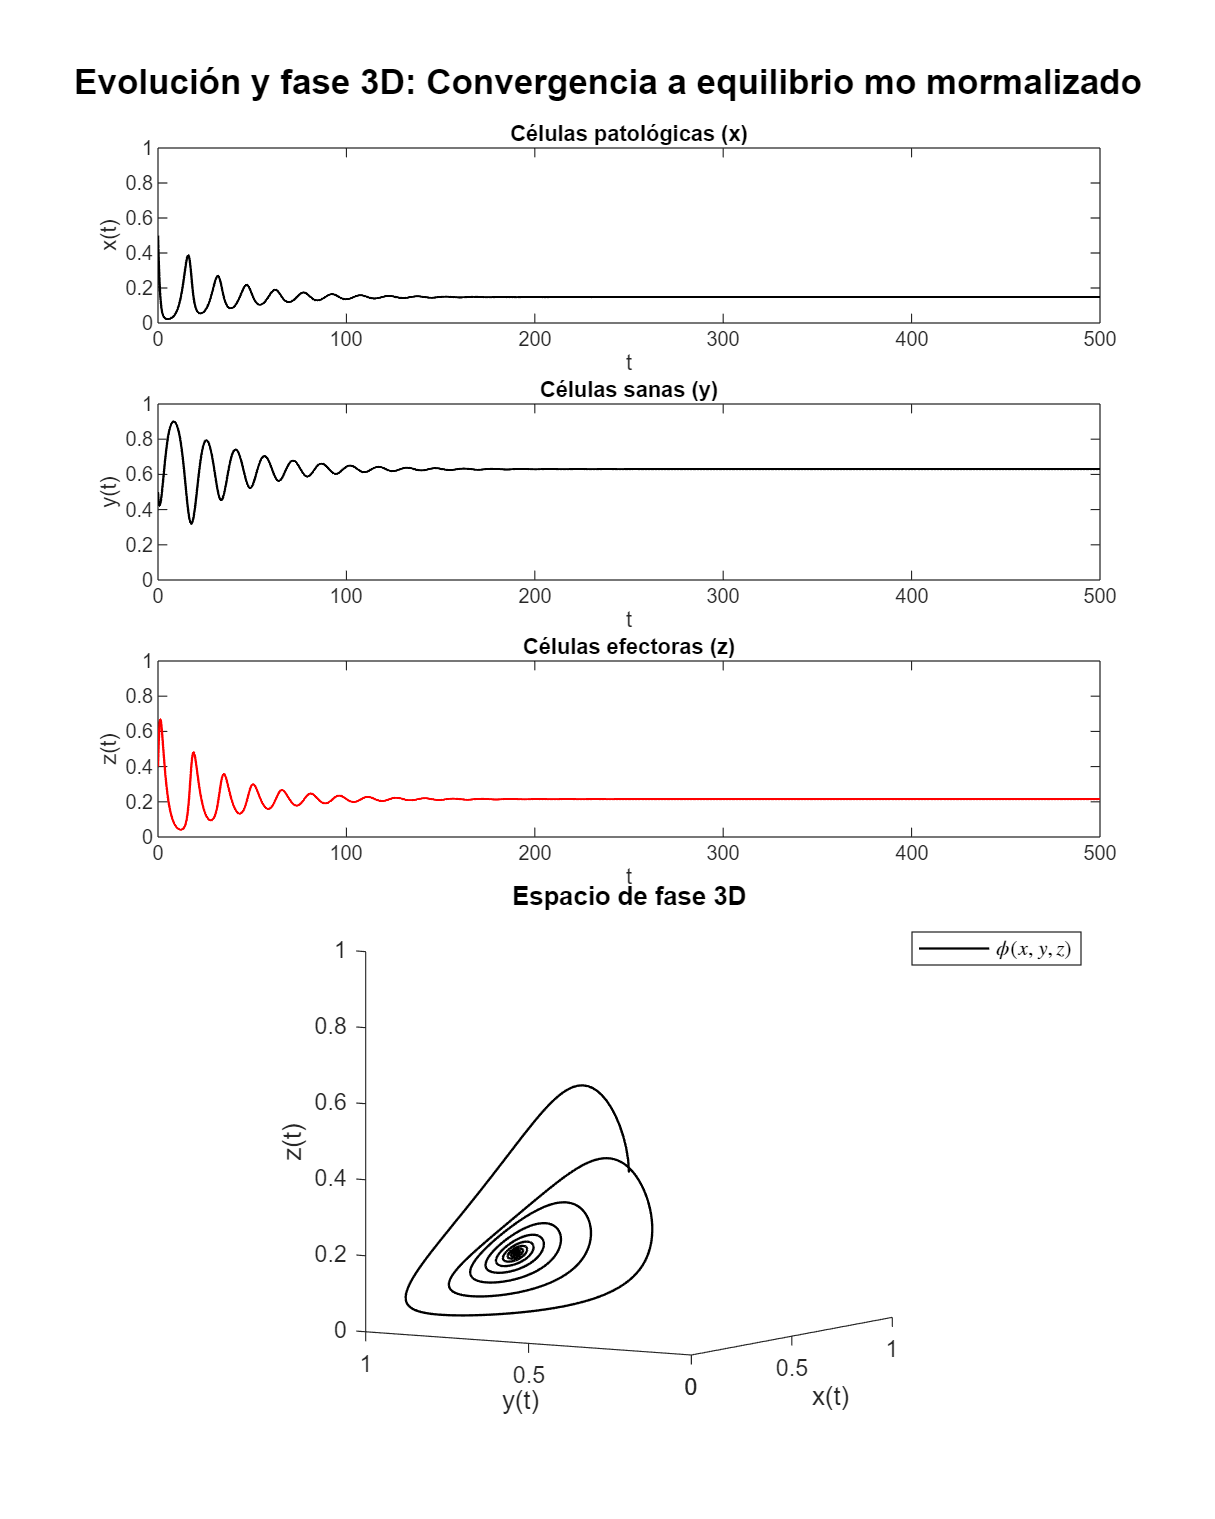

    r1 = 1;    b1 =1;     a13 = 2.5;
    r2 = 0.6;  b2 =1;     a21 = 1.5;
    r3 = 3;   a31 =0.3;    d3 = 0.4;
    P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
    rhoi=0;
    dt = 1E-1;

% Definir las dinámicas
dinamicas = {
    1, 1.0, 1500, [0.555, 0.148, 0.172], 'Atractor caótico no normalizado';
    2, 0.9, 400, [0.254781, 0.115167, 0.600527], 'Órbita periódica no normalizado';
    3, 0.8, 600, [0.2, 0.6, 0.1], 'Ciclo límite interno no normalizado';
    4, 0.75, 600, [0.4, 0.2, 0.4], 'Ciclo límite externo no normalizado';
    5, 0.5, 500, [0.5, 0.5, 0.4], 'Convergencia a equilibrio mo mormalizado';
};

for i = 1:size(dinamicas,1)
    dinamica = dinamicas{i,5};
    a12 = dinamicas{i,2};
    tend = dinamicas{i,3};
    condiciones = dinamicas{i,4};
    x0 = condiciones(1);
    y0 = condiciones(2);
    z0 = condiciones(3);

    [t, x, y, z] = system(x0, y0, z0, P, a12, rhoi, dt, tend);
    plotEDOs(t, x, y, z, dinamica, i, tend);
end

## Parameters an initial conditions [convergencia al equilibrio]

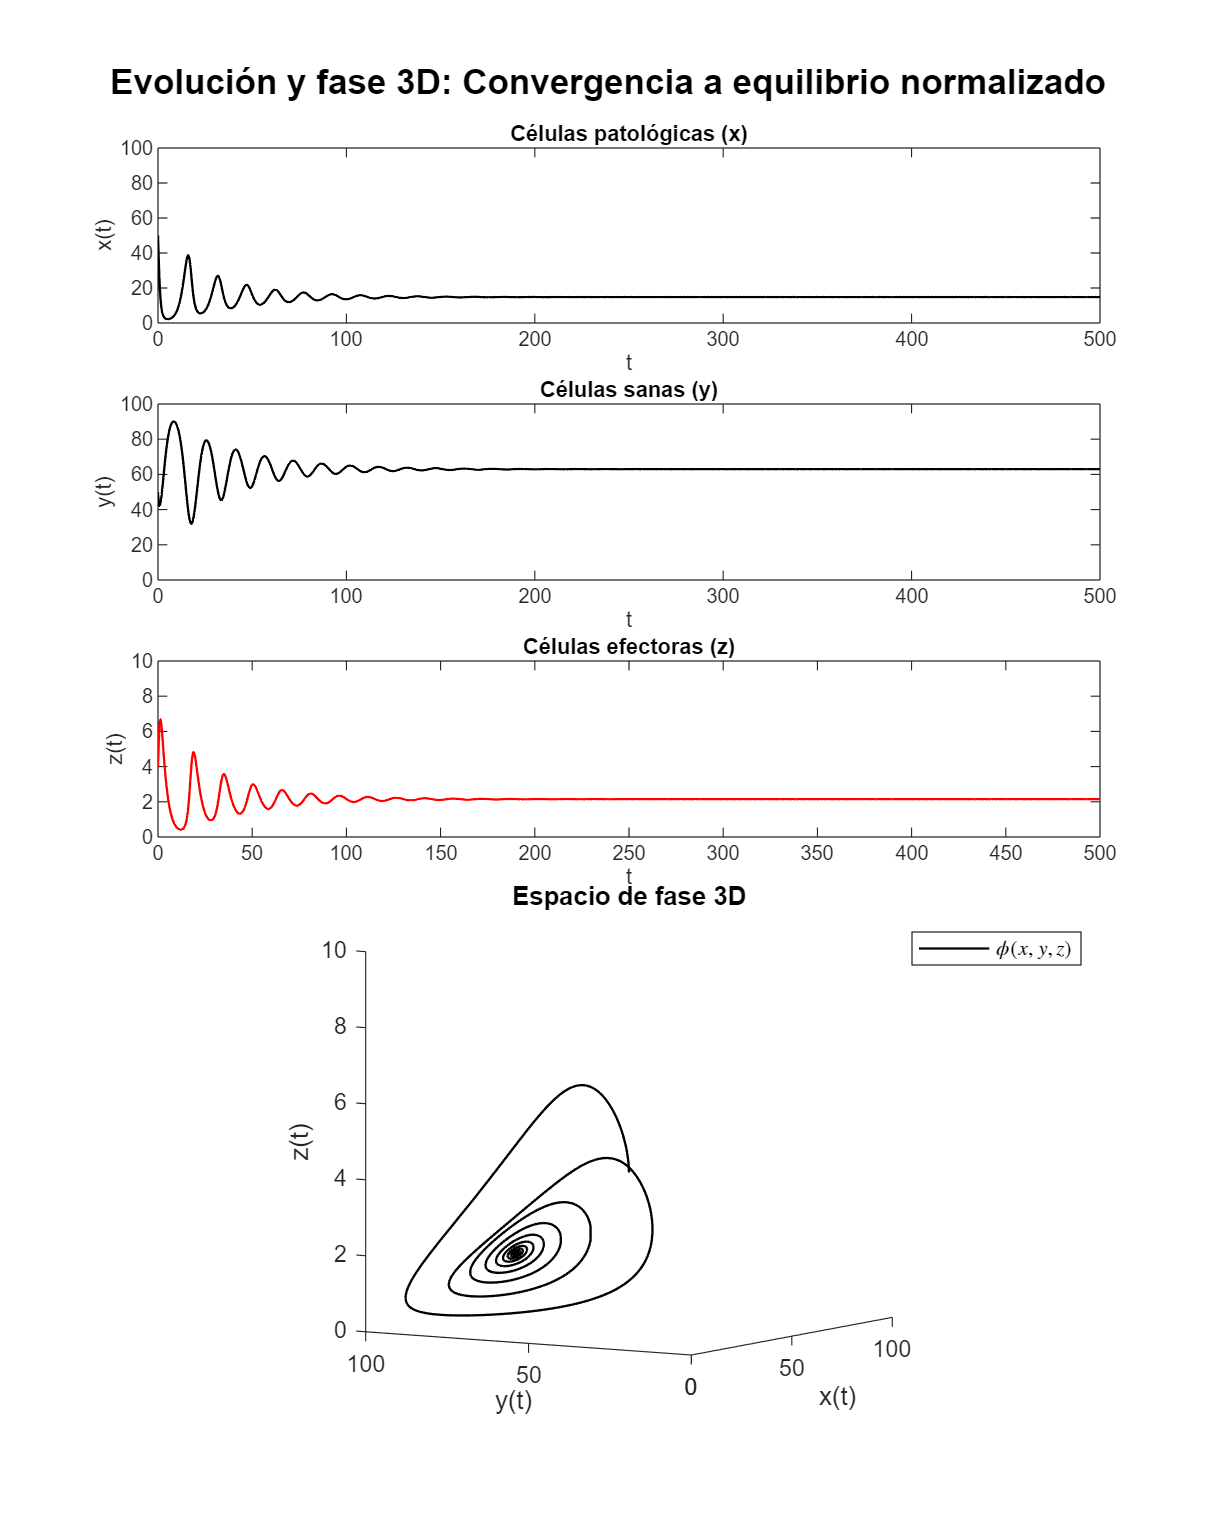

    xmax =1E2; ymax=1E2; zmax=1E1;
    r1 = 1;    b1 =1/xmax;     a13 = 2.5/zmax;
    r2 = 0.6;  b2 =1/ymax;     a21 = 1.5/xmax;
    r3 = 3/xmax;   a31 =0.3/xmax;    d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
x0 = 0.555*xmax;    y0= 0.148*ymax;  z0= 0.172*zmax;   a12=1/ymax;   rhoi=0; tend = 1000;
dt = 1E-2;

% Definir las dinámicas
dinamicas = {
    %1, 1.0, 1500, [0.555, 0.148, 0.172], 'Atractor caótico';
    %2, 0.9, 400, [0.254781, 0.115167, 0.600527], 'Órbita periódica';
    %3, 0.8, 600, [0.2, 0.6, 0.1], 'Ciclo límite interno';
    %4, 0.75, 600, [0.4, 0.2, 0.4], 'Ciclo límite externo';
    5, 0.5/ymax, 500, [0.5*xmax, 0.5*ymax, 0.4*zmax], 'Convergencia a equilibrio normalizado';
};

for i = 1:size(dinamicas,1)
    dinamica = dinamicas{i,5};
    a12 = dinamicas{i,2};
    tend = dinamicas{i,3};
    condiciones = dinamicas{i,4};
    x0 = condiciones(1);
    y0 = condiciones(2);
    z0 = condiciones(3);

    [t, x, y, z] = system(x0, y0, z0, P, a12, rhoi, dt, tend);
    plotEDOsNormalized(t, x, y, z, dinamica, i, tend);
end

## Equilibrium Points and Jacobian matrix

clear
syms x y z r1 b1 a12 a13 r2 b2 a21 r3 a31 d3 rhoi

dx = r1*x*(1-b1*x) - a12*x*y - a13*x*z;
dy = r2*y*(1-b2*y) - a21*x*y;
dz = (r3 - a31)*x*z - d3*z + rhoi;
J = jacobian([dx,dy,dz],[x,y,z]); disp(J)

$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{21}\,y & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$


dx = r1*x*(1-b1*x) - a12*x*y - a13*x*z == 0;
dy = r2*y*(1-b2*y) - a21*x*y == 0;
dz = (r3 - a31)*x*z - d3*z + rhoi == 0;
equilibria = solve([dx,dy,dz],[x,y,z]);
for i = 1:6
    xe(i,1) = simplify(equilibria.x(i));
    ye(i,1) = simplify(equilibria.y(i));
    ze(i,1) = simplify(equilibria.z(i));

    fprintf(['Equilibrium points of the system: ', num2str(i), '\n'])
    fprintf(['x', num2str(i), '=', char(xe(i,1)), '\n']);
    fprintf(['y', num2str(i), '=', char(ye(i,1)), '\n']);
    fprintf(['z', num2str(i), '=', char(ze(i,1)), '\n']);
end

Equilibrium points of the system: 1


x1=(a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3))


y1=0


z1=(a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 2


x2=-((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y2=(r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z2=-((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 3


x3=((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y3=(r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z3=((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 4


x4=0


y4=1/b2


z4=rhoi/d3


Equilibrium points of the system: 5


x5=-(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3))


y5=0


z5=(a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 6


x6=0


y6=0


z6=rhoi/d3


## Equilibrium Points non treatment

clear 
a12i = [1; 0.9; 0.8; 0.75; 0.5];
    r1 = 1;      b1 = 1;     a13 = 2.5;
    r2 = 0.6;    b2 = 1;     a21 = 1.5;
    r3 = 3;      a31 = 0.3;   d3 = 0.4;
    rhoi=0;
    for i = numel(0.5)
        a12 = 0.5;
     
        %Equilibrium points of the system: 1
        x1=(a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
        y1=0;
        z1=(a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
        %Equilibrium points of the system: 2
        x2=-((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        y2=(r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        z2=-((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
        %Equilibrium points of the system: 3
        x3=((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        y3=(r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        z3=((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
        %Equilibrium points of the system: 4
        x4=0;
        y4=1/b2;
        z4=rhoi/d3;
        %Equilibrium points of the system: 5
        x5=-(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
        y5=0;
        z5=(a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
        %Equilibrium points of the system: 6
        x6=0;
        y6=0;
        z6=rhoi/d3;

        x = [x1; x2; x3; x4; x5; x6;]; y = [y1; y2; y3; y4; y5; y6;]; z = [z1; z2; z3; z4; z5; z6;]; 
        fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
        fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])

        for j = 1:numel(x)
            J = [
              -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),                           -a12*x(j),                          -a13*x(j);
                                                         -a21*y(j),     -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),                        0;
                                                  -z(j)*(a31 - r3),                                             0,       -d3*x(j)*(a31 - r3)];
         L(j,:) = eig(J);
        end

        Lambda1 = L(:,1);  Lambda2 = L(:,2);  Lambda3 = L(:,3);

        Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
        disp(Results)
    end

Equilibrium points with a12 = 0.5


Treatment rhoi = 0


       x          y           z              Lambda1               Lambda2              Lambda3     
    _______    _______    __________    __________________    __________________    ________________

    0.14815          0       0.34074    0.0059259+0.56303i    0.0059259-0.56303i    0.37778+0i      
    0.14815    0.62963       0.21481     -0.48241+0i            0.05824+0.41167i    0.05824-0.41167i
         -2          6             0         -0.8+1.077i           -0.8-1.077i        -2.16+0i      
          0          1             0         -0.6+0i                0.5+0i                0+0i      
          1          0    2.4672e-17           -1+0i               1.08+0i             -0.9+0i      
          0          0             0            0+0i                0.6+0i              

## Equilibrium Points with treatment

clear 
a12i = [1; 0.9; 0.8; 0.75; 0.5];
    r1 = 1;      b1 = 1;     a13 = 2.5;
    r2 = 0.6;    b2 = 1;     a21 = 1.5;
    r3 = 3;      a31 = 0.3;   d3 = 0.4;
    rhoi = 1.1*(d3*r1)/a13;
    for i = numel(0.5)
        a12 = 0.5;
     
        %Equilibrium points of the system: 1
        x1=(a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
        y1=0;
        z1=(a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
        %Equilibrium points of the system: 2
        x2=-((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        y2=(r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        z2=-((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
        %Equilibrium points of the system: 3
        x3=((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        y3=(r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
        z3=((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
        %Equilibrium points of the system: 4
        x4=0;
        y4=1/b2;
        z4=rhoi/d3;
        %Equilibrium points of the system: 5
        x5=-(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
        y5=0;
        z5=(a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
        %Equilibrium points of the system: 6
        x6=0;
        y6=0;
        z6=rhoi/d3;

        x = [x1; x2; x3; x4; x5; x6;]; y = [y1; y2; y3; y4; y5; y6;]; z = [z1; z2; z3; z4; z5; z6;]; 
        fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
        fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])

        for j = 1:numel(x)
            J = [
              -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),                           -a12*x(j),                          -a13*x(j);
                                                         -a21*y(j),     -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),                        0;
                                                  -z(j)*(a31 - r3),                                             0,       -d3*x(j)*(a31 - r3)];
         L(j,:) = eig(J);
        end

        Lambda1 = L(:,1);  Lambda2 = L(:,2);  Lambda3 = L(:,3);

        Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
        disp(Results)
    end

Equilibrium points with a12 = 0.5


Treatment rhoi = 0.176


        x          y           z        Lambda1          Lambda2              Lambda3     
    _________    ______    _________    ________    _________________    _________________

    -0.012761         0       0.4051     0.18676    -0.18778+0i           0.61914+0i      
     -0.21756    1.5439      0.17824     0.42689    -0.68532+0.26573i    -0.68532-0.26573i
      -1.6343    5.0857     0.036571    -0.46672     -1.3577+0.48356i     -1.3577-0.48356i
            0         1         0.44           0        -0.6+0i              -0.6+0i      
       1.1609         0    -0.064364     -1.3543      1.4472+0i           -1.1414+0i      
            0         0         0.44           0        -0.1+0i               0.6+0i      



## Parameters an initial conditions [convergencia al equilibrio]

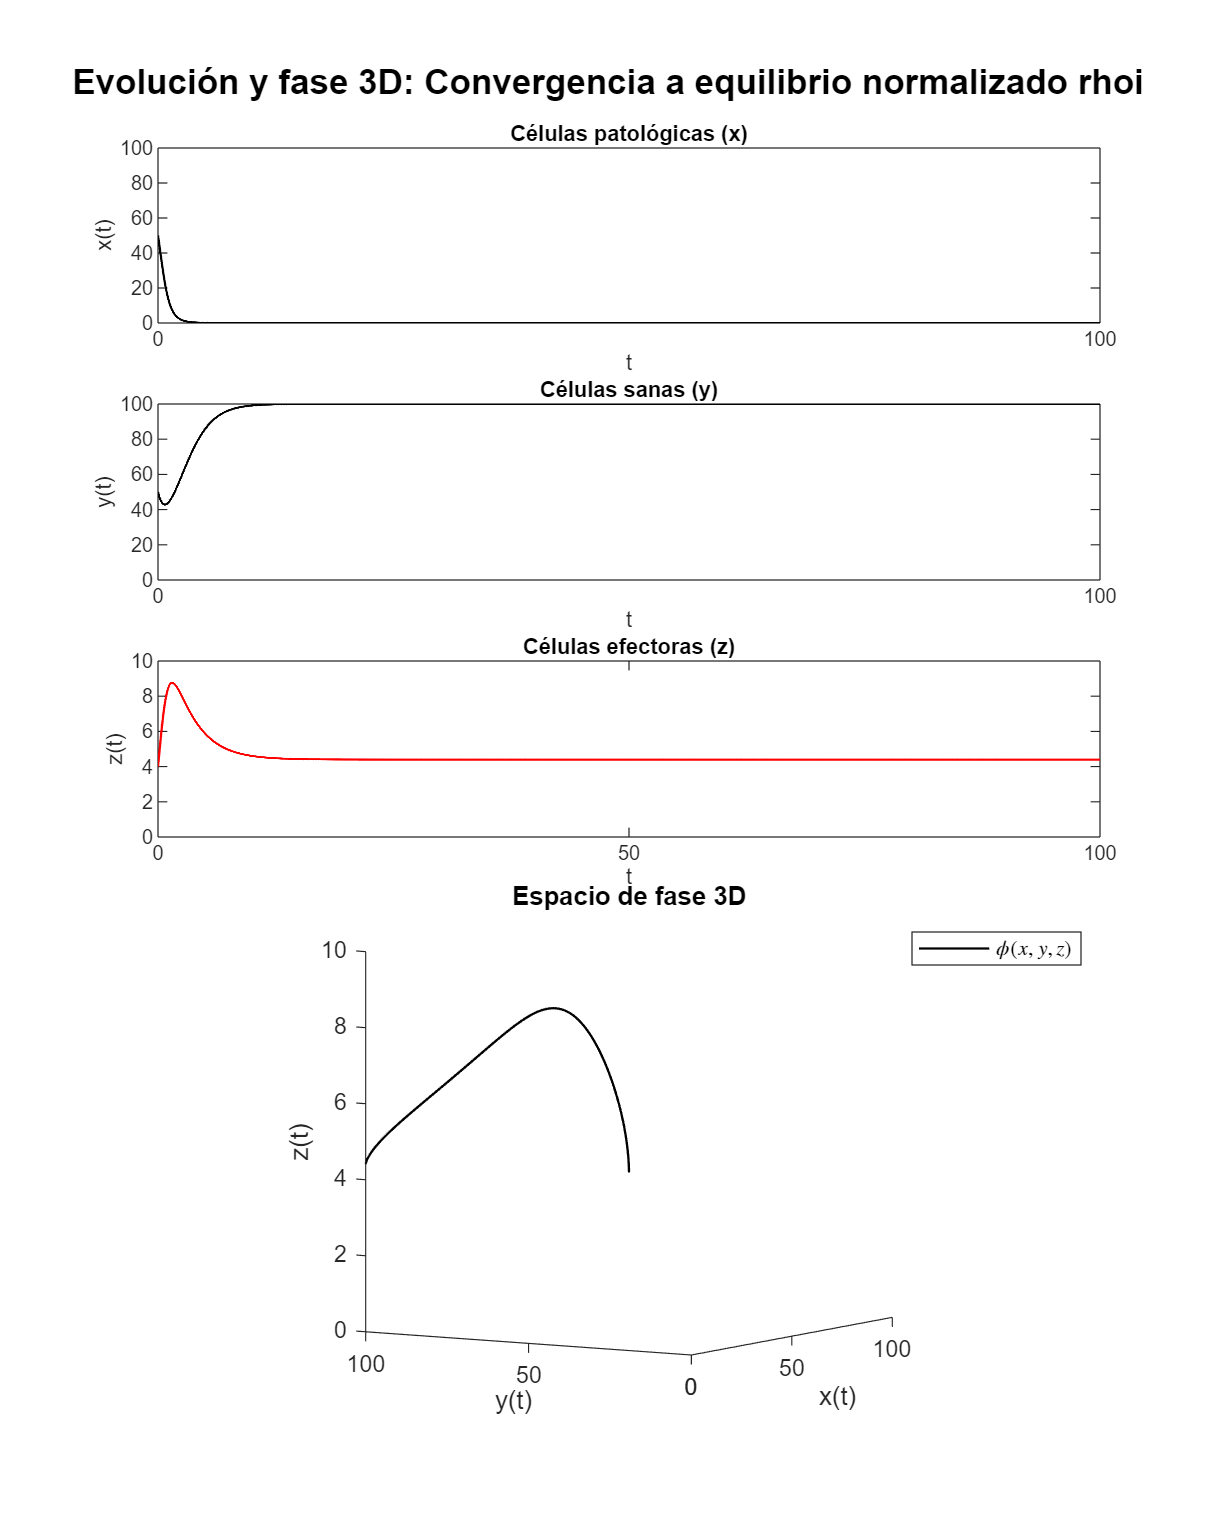

    xmax =1E2; ymax=1E2; zmax=1E1;
    r1 = 1;    b1 =1/xmax;     a13 = 2.5/zmax;
    r2 = 0.6;  b2 =1/ymax;     a21 = 1.5/xmax;
    r3 = 3/xmax;   a31 =0.3/xmax;    d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
x0 = 0.555*xmax;    y0= 0.148*ymax;  z0= 0.172*zmax;   a12=1/ymax;   rhoi=1.1*(d3*r1)/a13; tend = 1000;
dt = 1E-2;

% Definir las dinámicas
dinamicas = {
    %1, 1.0, 1500, [0.555, 0.148, 0.172], 'Atractor caótico';
    %2, 0.9, 400, [0.254781, 0.115167, 0.600527], 'Órbita periódica';
    %3, 0.8, 600, [0.2, 0.6, 0.1], 'Ciclo límite interno';
    %4, 0.75, 600, [0.4, 0.2, 0.4], 'Ciclo límite externo';
    5, 0.5/ymax, 100, [0.5*xmax, 0.5*ymax, 0.4*zmax], 'Convergencia a equilibrio normalizado rhoi';
};

for i = 1:size(dinamicas,1)
    dinamica = dinamicas{i,5};
    a12 = dinamicas{i,2};
    tend = dinamicas{i,3};
    condiciones = dinamicas{i,4};
    x0 = condiciones(1);
    y0 = condiciones(2);
    z0 = condiciones(3);

    [t, x, y, z] = system(x0, y0, z0, P, a12, rhoi, dt, tend);
    plotEDOsNormalized(t, x, y, z, dinamica, i, tend);
end

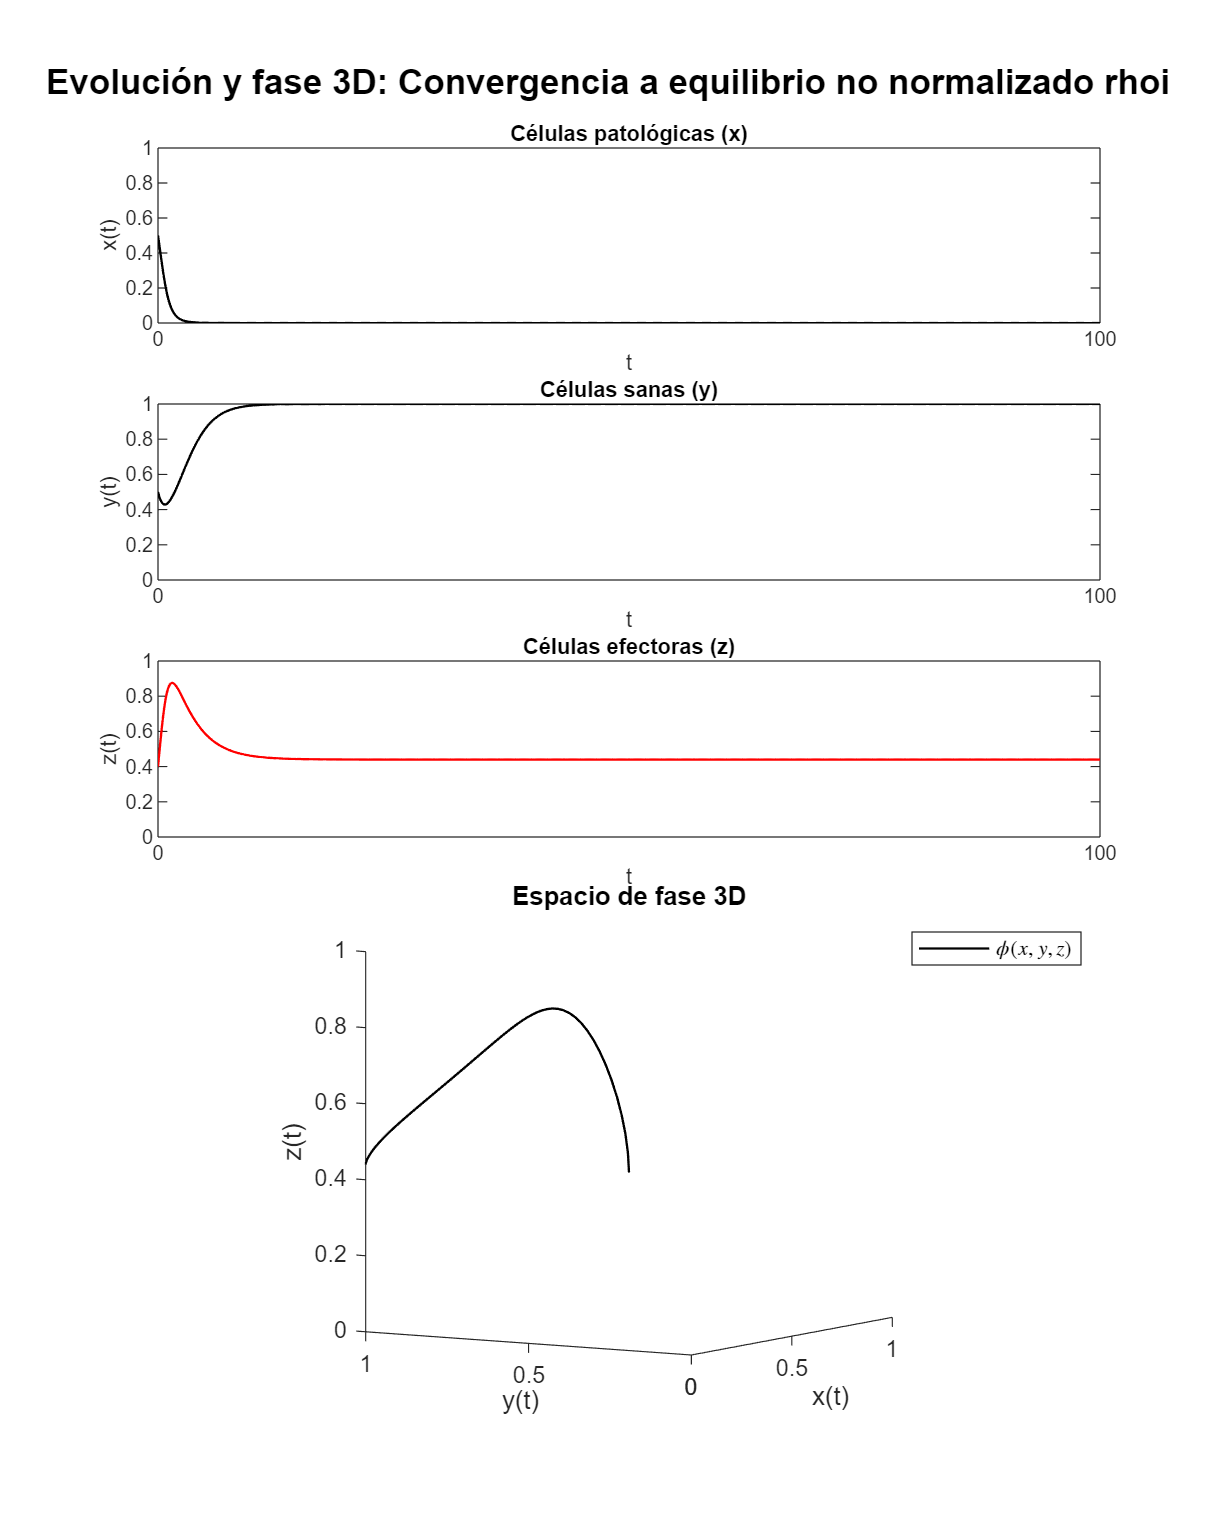

    r1 = 1;    b1 =1;     a13 = 2.5;
    r2 = 0.6;  b2 =1;     a21 = 1.5;
    r3 = 3;   a31 =0.3;    d3 = 0.4;
    P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
    rhoi=1.1*(d3*r1)/a13;
    dt = 1E-1;

% Definir las dinámicas
dinamicas = {
    %1, 1.0, 1500, [0.555, 0.148, 0.172], 'Atractor caótico';
    %2, 0.9, 400, [0.254781, 0.115167, 0.600527], 'Órbita periódica';
    %3, 0.8, 600, [0.2, 0.6, 0.1], 'Ciclo límite interno';
    %4, 0.75, 600, [0.4, 0.2, 0.4], 'Ciclo límite externo';
    5, 0.5, 100, [0.5, 0.5, 0.4], 'Convergencia a equilibrio no normalizado rhoi';
};

for i = 1:size(dinamicas,1)
    dinamica = dinamicas{i,5};
    a12 = dinamicas{i,2};
    tend = dinamicas{i,3};
    condiciones = dinamicas{i,4};
    x0 = condiciones(1);
    y0 = condiciones(2);
    z0 = condiciones(3);

    [t, x, y, z] = system(x0, y0, z0, P, a12, rhoi, dt, tend);
    plotEDOs(t, x, y, z, dinamica, i, tend);
end

## Funciones

### Sistema

function [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend)
    r1 = P(1); b1 = P(2); a13 = P(3);
    r2 = P(4); b2 = P(5); a21 = P(6);
    r3 = P(7); a31 = P(8); d3 = P(9);
    
    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(n+1,1); x(1) = x0;
    y = zeros(n+1,1); y(1) = y0;
    z = zeros(n+1,1); z(1) = z0;

    for i = 1:n
        [fx, fy, fz] = f(x(i), y(i), z(i));
        xn = x(i) + fx * dt;
        yn = y(i) + fy * dt;
        zn = z(i) + fz * dt;

        [fxn, fyn, fzn] = f(xn, yn, zn);
        x(i+1) = x(i) + (fx + fxn) * dt / 2;
        y(i+1) = y(i) + (fy + fyn) * dt / 2;
        z(i+1) = z(i) + (fz + fzn) * dt / 2; % CORREGIDO aquí, usas fzn no fxn
    end

    function [dx, dy, dz] = f(x, y, z)
        dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
        dy = r2*y*(1 - b2*y) - a21*x*y;
        dz = (r3 - a31)*x*z - d3*z + rhoi;
    end
end

## Plots

function plotEDOs(t, x, y, z, interactionName, num_interaction, tend)
    % Figura general: más grande y editable
    figure('Position', [100, 50, 800, 1000]);  % 🔥 Tamaño ancho x alto

    % Gráfica de x(t)
    subplot(5,1,1)
    plot(t, x, 'k', 'LineWidth', 1);
    title('Células patológicas (x)');
    xlabel('t');
    ylabel('x(t)');
    xlim([0 tend]); xticks(0:100:tend)
    ylim([0 1]);    yticks(0:0.2:1)
    grid off;

    % Gráfica de y(t)
    subplot(5,1,2)
    plot(t, y, 'k', 'LineWidth', 1);
    title('Células sanas (y)');
    xlabel('t');
    ylabel('y(t)');
    xlim([0 tend]); xticks(0:100:tend)
    ylim([0 1]);    yticks(0:0.2:1)
    grid off;

    % Gráfica de z(t)
    subplot(5,1,3)
    plot(t, z, 'r', 'LineWidth', 1);
    title('Células efectoras (z)');
    xlabel('t');
    ylabel('z(t)');
    xlim([0 tend]); xticks(0:100:tend)
    ylim([0 1]);    yticks(0:0.2:1)
    grid off;

    % Espacio de fase 3D
    subplot(5,1,[4 5])
    plot3(y, x, z, 'k', 'LineWidth', 1);
    title('Espacio de fase 3D');
    xlabel('y(t)');
    ylabel('x(t)');
    zlabel('z(t)');
    xlim([0 1]);     xticks(0:0.5:1)
    ylim([0 1]);     yticks(0:0.5:1)
    zlim([0 1]);     zticks(0:0.2:1)

    L = legend('$\phi(x,y,z)$');
    set(L, 'Interpreter', 'latex', 'Location', 'northeast', 'Box', 'on');

    set(gca, 'XDir', 'reverse'); 
    grid off;
    axis square;
    view(31.674, 6.637); % puedes moverlo después manualmente si quieres

    % Título general
    sgtitle(['Evolución y fase 3D: ' interactionName], 'FontWeight', 'bold');

    % Exportar toda la figura completa
    exportgraphics(gcf, ['Completo_'  interactionName '.pdf'], 'ContentType', 'Vector');
end


function plotEDOsNormalized(t, x, y, z, interactionName, num_interaction, tend)
    % Figura general: más grande y editable
    figure('Position', [100, 50, 800, 1000]);  % 🔥 Tamaño ancho x alto

    % Gráfica de x(t)
    subplot(5,1,1)
    plot(t, x, 'k', 'LineWidth', 1);
    title('Células patológicas (x)');
    xlabel('t');
    ylabel('x(t)');
    xlim([0 tend]);   xticks(0:100:tend)
    ylim([0 100]);    yticks(0:20:100)
    grid off;

    % Gráfica de y(t)
    subplot(5,1,2)
    plot(t, y, 'k', 'LineWidth', 1);
    title('Células sanas (y)');
    xlabel('t');
    ylabel('y(t)');
    xlim([0 tend]);  xticks(0:100:tend)
    ylim([0 100]);   yticks(0:20:100)
    grid off;

    % Gráfica de z(t)
    subplot(5,1,3)
    plot(t, z, 'r', 'LineWidth', 1);
    title('Células efectoras (z)');
    xlabel('t');
    ylabel('z(t)');
    xlim([0 tend]);  xticks(0:50:tend)
    ylim([0 10]);    yticks(0:2:10)
    grid off;

    % Espacio de fase 3D
    subplot(5,1,[4 5])
    plot3(y, x, z, 'k', 'LineWidth', 1);
    title('Espacio de fase 3D');
    xlabel('y(t)');
    ylabel('x(t)');
    zlabel('z(t)');
    xlim([0 100]);     xticks(0:50:100)
    ylim([0 100]);     yticks(0:50:100)
    zlim([0 10]);      zticks(0:2:10)

    L = legend('$\phi(x,y,z)$');
    set(L, 'Interpreter', 'latex', 'Location', 'northeast', 'Box', 'on');

    set(gca, 'XDir', 'reverse'); 
    grid off;
    axis square;
    view(31.674, 6.637); % puedes moverlo después manualmente si quieres

    % Título general
    sgtitle(['Evolución y fase 3D: ' interactionName], 'FontWeight', 'bold');

    % Exportar toda la figura completa
    exportgraphics(gcf, ['Completo_normalizado'  '_' interactionName '.pdf'], 'ContentType', 'Vector');
end